direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;

shape_step = 0.05;
% shape is alpha; shapechange is alpha dot
a = s.grid_range(1):shape_step:s.grid_range(2);
adot = -0.5:0.01:0.5;

agree = cell(length(s.geometry.linklengths), 4);

for dir = 0:3
    backwards = [mod(dir,2), floor(dir/2)]; % this is a hacky way to do all 4 direction combos with binary
    friction_direction = [1, 1] - 2 * backwards;
    
    % storage of results for each link
    %agree = cell(size(s.geometry.linklengths));
    % how do I do this without hardcoding?
    agree{1, dir + 1} = zeros(length(a), length(adot));
    agree{2, dir + 1} = zeros(length(a), length(adot));
    for i = 1:length(a)
        shape = a(i);
        
        % these two don't depend on alpha dot:
        % get A(alpha)
        [A, ~, ~, ~, ~] = LowRE_connection_discrete(s.geometry, s.physics, shape, backwards);
        % get Jfull(alpha)
        [~, ~, J_full, ~, ~] = N_link_chain(s.geometry, shape);
        
        for j = 1:length(adot)
            shapechange = adot(j);
            
            % gcirc right
            body_vel = A * shapechange;
    
            for link = 1:length(s.geometry.linklengths)
                body_vel = J_full{link} * [body_vel; shapechange];
                dx_direction = sign(body_vel(1)); %index 1 is x, right?
                if(dx_direction == 0) % non-if way to do this?
                    agreement = 1;
                else
                    agreement = friction_direction(link) * dx_direction;
                end
                agree{link, dir + 1}(i,j) = agreement;
            end
        end
    end
end

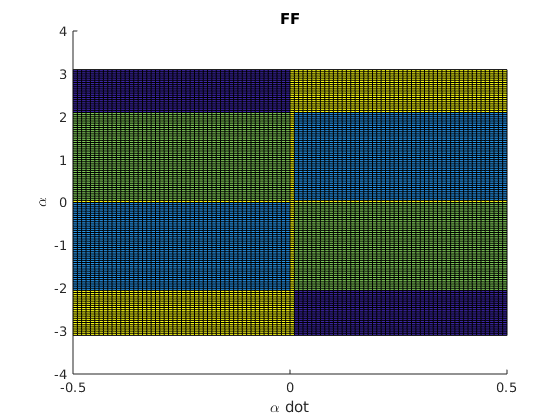

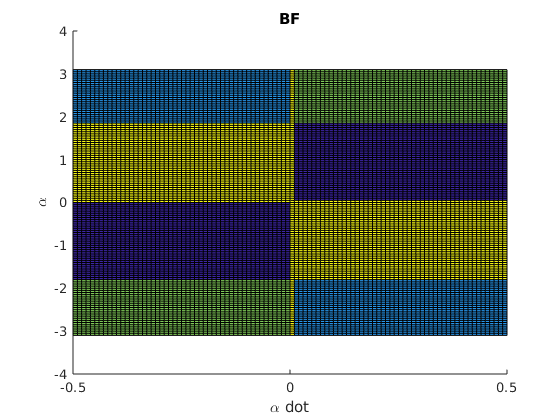

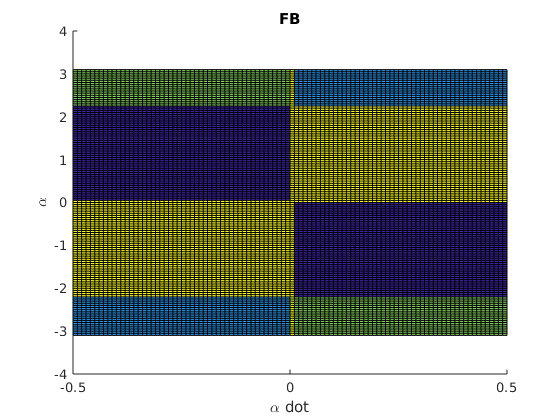

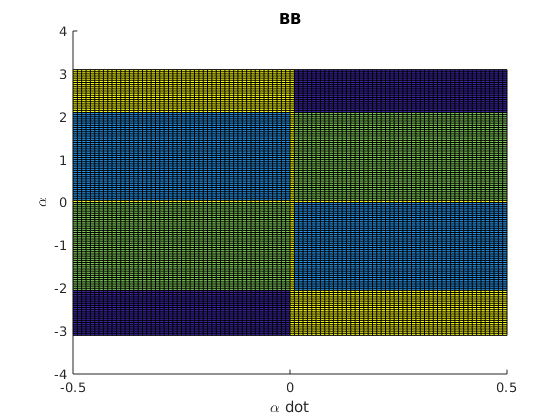

for dir = 0:3
    figure(dir+1);
    clf(dir+1);
    title(direction_names(dir+1));
    xlabel("\alpha dot");
    ylabel("\alpha");
    % summary: link 1 is the 1's digit in binary. link 2 is the 2's digit.
    % so 00 would be agreeing with neither, 10 (= 2) would be agreeing with
    % just link 2, 01 (= 1) would be agreeing with just link 1, and 11 (= 3)
    % would be agreeing with both
    summary = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
    %summary = (agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1);
    surface(adot, a, summary);
end

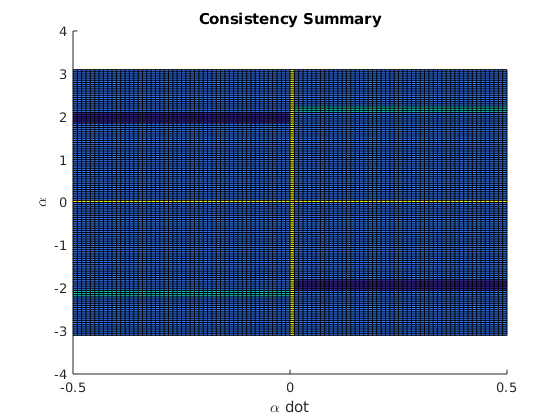


% keep track of any places where there's no solution, one, or multiple
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
direction_summary = zeros(size(agree{1, 1}));
for dir = 0:3
    direction_summary = direction_summary + ((agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1));
end
surface(adot, a, direction_summary);

dir = 0; FF = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
dir = 1; BF = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
dir = 2; FB = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
dir = 3; BB = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);

% each matrix is pi rotationally symmetric
all(rot90(FF,2) == FF, 'all')

ans = logical
   1


all(rot90(BF,2) == BF, 'all')

ans = logical
   1


all(rot90(FB,2) == FB, 'all')

ans = logical
   1


all(rot90(BB,2) == BB, 'all')

ans = logical
   1


% each matrix is adot-translationally symmetric
% (on each side of axis)
find(any(FF(:,1:size(FF,2)-1) - FF(:,2:size(FF,2)))) == [50 51] %#ok<*EQEFF> 

ans = 1×2 logical array
   1   1


find(any(BF(:,1:size(BF,2)-1) - BF(:,2:size(BF,2)))) == [50 51]

ans = 1×2 logical array
   1   1


find(any(FB(:,1:size(FB,2)-1) - FB(:,2:size(FB,2)))) == [50 51]

ans = 1×2 logical array
   1   1


find(any(BB(:,1:size(BB,2)-1) - BB(:,2:size(BB,2)))) == [50 51]

ans = 1×2 logical array
   1   1



% but not alpha symmetric, of course
find(any(FF(1:size(FF,1)-1,:) - FF(2:size(FF,1),:)))

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% so we can just take a strip of each matrix at alpha = 1 (or whatever)
% and use it to know the entire rest of the matrix
FFs = FF(:,55);
BFs = BF(:,55);
FBs = FB(:,55);
BBs = BB(:,55);
DSs = direction_summary(:,55);

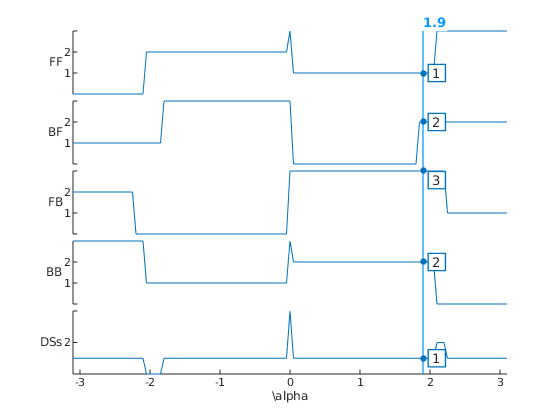

figure()
clf
newYlabels = {'FF','BF','FB','BB', 'DSs'};
stackedplot(a,[FFs BFs FBs BBs DSs], 'DisplayLabels',newYlabels);
xlabel('\alpha');

% There is a mirror symmetry accross the alpha=0 line.
% The consistency values are notted for each link,
% so a point at a=-1 that's consistent in both links would be
% inconsistent in both links at a=1.
A = FFs;
n = ceil(length(A)/2); % index of alpha = 0
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   1


A = BFs;
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   1


A = FBs;
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   1


A = BBs;
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   1


% mod(FFs,2); % originally 1's component
% floor(FFs/2); % originally 2's component
% not 0 is 3 (00; 11)
% not 1 is 2 (01; 10)
% ~(mod(FFs,2)) + ~(floor(FFs/2))*2; % negate each and rebuild

% See where changes occur.
a(FFs(1:length(FFs)-1) - FFs(2:length(FFs))~=0)

ans =    -2.1000   -0.0500         0    2.0500


a(BBs(1:length(BBs)-1) - BBs(2:length(BBs))~=0)

ans =    -2.1000   -0.0500         0    2.0500


a(BFs(1:length(BFs)-1) - BFs(2:length(BFs))~=0)

ans =    -1.8500         0    1.8000


a(FBs(1:length(FBs)-1) - FBs(2:length(FBs))~=0)

ans =    -2.2500   -0.0500    2.2000


a(DSs(1:length(DSs)-1) - DSs(2:length(DSs))~=0)

ans =    -2.1000   -1.8500   -0.0500         0    2.0500    2.2000



% FF and BB change at the same spot,
% but BF and FB don't line up as nicely.